# Drone Arm 1 FEA 

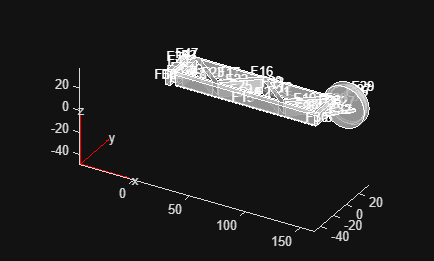

% Load in Material properties
prop = load('droneArmMaterials.mat');
exa = materials(2).yieldStrength_Pa;
% 1 Carbon Fiber Composite
% 2 Aluminum Alloy
% 3 Fiberglass Composite
% 4 PLA Plastic
% 5 ABS Plastic
% 6 Wood (Birch)


% Import CAD file
gm = importGeometry("DRONE ARM.STL"); % Note: CAD model is flipped on it's side (+y is up)
pdegplot(gm,FaceLabels="on",FaceAlpha=0.7)



% Create mesh of CAD file
% md = [0 0]
md = femodel(AnalysisType="structuralStatic",Geometry=gm);
md = generateMesh(md, Hmin=1);
%pdemesh(md)

% Add in Material properties onto Mesh
n = 3;
md.MaterialProperties = materialProperties(...
YoungsModulus=prop.materials(n).E_Pa,... 
MassDensity=prop.materials(n).rho_kg_m3,... 
PoissonsRatio=prop.materials(n).nu);

% md(2).MaterialProperties = materialProperties(...
%     YoungsModulus=prop.materials(n).E_Pa,... 
%     MassDensity=prop.materials(n).rho_kg_m3,... 
%     PoissonsRatio=prop.materials(n).nu);


% LOADS:
% Add in constraint (End of Drone Arm)
md.FaceBC(39) = faceBC(Constraint="fixed");

% Factor in weight of drone arm
md.CellLoad = cellLoad(Gravity=[0 -9.8 0]);  % Gravity applied in y instead of z

% Factor in thrust force of propeller (1kg per prop)
% TotalT = 1 * 9.8; %F = m*a(+g) (N)
% AreaProp = 5; %Area of propeller mount (m^2)
% TPressure = TotalT/AreaProp; %Pressure of Thrust 
TPressure = 10;
md.FaceLoad(36) = faceLoad(SurfaceTraction = [0 TPressure 0]); %Possible error could come from putting in wrong face (36)*

% Factor in weight of drone components in body (1kg)
% TotalW = 1 * -9.8; %F(g) = m*a(g) (N)
% WOnArm = TotalW/4; %Assuming center of mass is at middle (N)
% AreaMount = 5; %Area of Drone arms mounting surface to the drone body (m^2)
% WPressure = WOnArm/AreaMount;
% md.FaceLoad(39) = faceLoad(SurfaceTraction = [0 WPressure 0]);

% Factor in Payload weight (min of 0.5kg)
% TotalP = 0.5 * -9.8; %F(g) = m*a(g) (N)
% PPressure = TotalP/AreaMount;
% md.FaceLoad(39) = faceLoad(SurfaceTraction = [0 PPressure 0]);


% Solve FEA
sol = solve(md);


% Visual of Results (x,y,z displacements and Von Mises Stress)

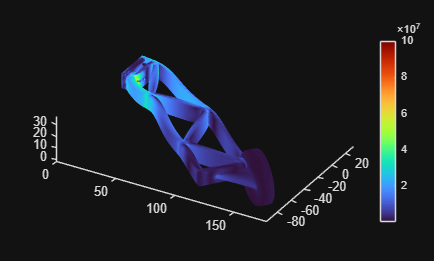

% Data to visualize
meshData = sol.Mesh;
nodalData = sol.VonMisesStress;
deformationData = sol.Displacement;

% Create PDE result visualization
resultViz = pdeviz(meshData,nodalData, ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",141.5493, ...
    "ColorLimits",[25550 100200000]);


% Clear temporary variables
clearvars meshData nodalData deformationData

% Calculating max displacement (in y direction)
maxDeflection = max(sol.Displacement.uy)

maxDeflection = 6.1142e-04


% Calculating max Von Mises Stress
maxStress = max(sol.VonMisesStress)

maxStress = 1.2009e+08


% How close to plastic deformation (yield strength)
per = 100 * maxStress/props.materials(n).yieldStrength_Pa

per = 40.0305


% Factor of Safety (keep 2:1 thrust to weight ratio)(or maybe this is
% resulting from how close we are to yield strength?)
